# Quadratic Spline Interpolation

clear all
close all
% points
X = [1 2 3 4 5 6];
Y = [5 1 8 3 6 9];
m = length(X);
% construction of the coefficient matrix
A = eye(m) % identity matrix

A =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


v = ones(1, m-1)

v =      1     1     1     1     1


A = A + diag(v, -1)

A =      1     0     0     0     0     0
     1     1     0     0     0     0
     0     1     1     0     0     0
     0     0     1     1     0     0
     0     0     0     1     1     0
     0     0     0     0     1     1


% construction of the right hand side
b = zeros(m, 1);
leftendderivative = 1; % arbitrary
b(1) = leftendderivative;

b =      1
     0
     0
     0
     0
     0


for k = 2:m
    b(k) = 2 * (Y(k) - Y(k-1))/(X(k) - X(k-1));
end
% system of derivatives
figure
plot(X,Y, 'ro')
hold on
Z = A\b

Z =      1
    -9
    23
   -33
    39
   -33


syms x
for k = 2:m
    frac(k) = 0.5*(Z(k) - Z(k-1))/(X(k) - X(k-1));
    pk = Z(k-1)*(x-X(k-1)) + frac(k) *(x - X(k-1))^2+Y(k-1);
    k-1;
    simplify (pk)
    fplot (pk, [X(k-1) X(k)])
end

$$ans = x-5\,{\left(x-1\right)}^{2}+4$$

$$ans = 16\,x^{2}-73\,x+83$$

$$ans = -28\,x^{2}+191\,x-313$$

$$ans = 36\,x^{2}-321\,x+711$$

$$ans = -36\,x^{2}+399\,x-1089$$

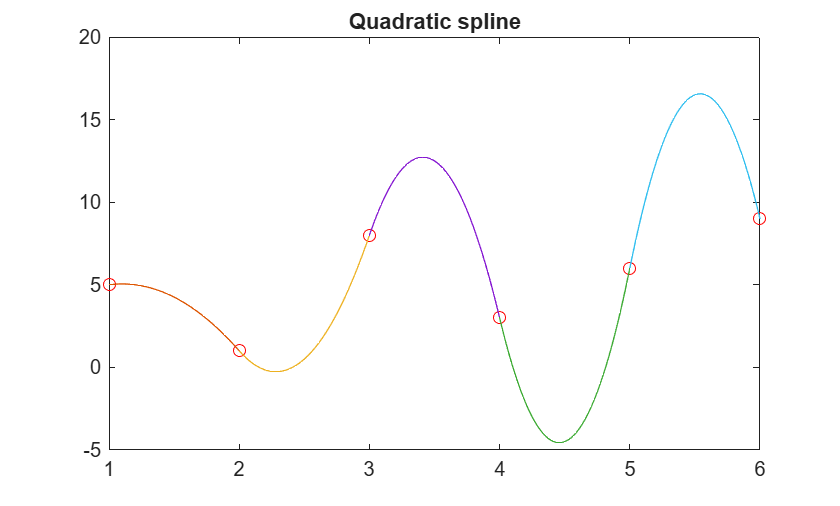

title('Quadratic spline')


 % Runge's examples
X = -5:1:5;
Y = 1./(1+X.^2);

m = length(X);
% construction of the coefficient matrix
A = eye(m); % identity matrix
v = ones(1, m-1);
A = A + diag(v, -1);
% construction of the right hand side
b = zeros(m, 1);
leftendderivative = -4; % arbitrary
b(1) = leftendderivative;
for k = 2:m
    b(k) = 2 * (Y(k) - Y(k-1))/(X(k) - X(k-1));
end
% system of derivatives
figure
plot(X,Y, 'ro')
hold on
Z = A\b;
syms x
for k = 2:m
    frac(k) = 0.5*(Z(k) - Z(k-1))/(X(k) - X(k-1));
    pk = Z(k-1)*(x-X(k-1)) + frac(k) *(x - X(k-1))^2+Y(k-1);
    k-1;
    simplify (pk)
    fplot (pk, [X(k-1) X(k)])
end

$$ans = \frac{1777\,{\left(x+5\right)}^{2}}{442}-4\,x-\frac{519}{26}$$

$$ans = \frac{893\,x}{221}-\frac{8839\,{\left(x+4\right)}^{2}}{2210}+\frac{3585}{221}$$

$$ans = \frac{8969\,x^{2}}{2210}+\frac{22533\,x}{1105}+\frac{27349}{1105}$$

$$ans = -\frac{8527\,x^{2}}{2210}-\frac{12459\,x}{1105}-\frac{7643}{1105}$$

$$ans = \frac{8969\,x^{2}}{2210}+\frac{5037\,x}{1105}+1$$

$$ans = -\frac{11179\,x^{2}}{2210}+\frac{5037\,x}{1105}+1$$

$$ans = \frac{11621\,x^{2}}{2210}-\frac{17763\,x}{1105}+\frac{2501}{221}$$

$$ans = -\frac{11179\,x^{2}}{2210}+\frac{27837\,x}{1105}-\frac{6619}{221}$$

$$ans = \frac{11309\,x^{2}}{2210}-\frac{2331\,x}{65}+\frac{68101}{1105}$$

$$ans = -\frac{11263\,x^{2}}{2210}+\frac{3897\,x}{85}-\frac{22495}{221}$$

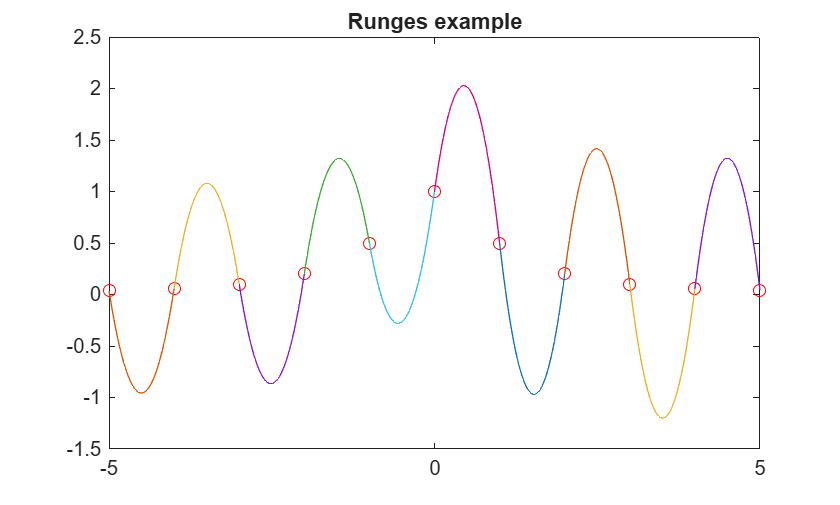

title('Runges example')